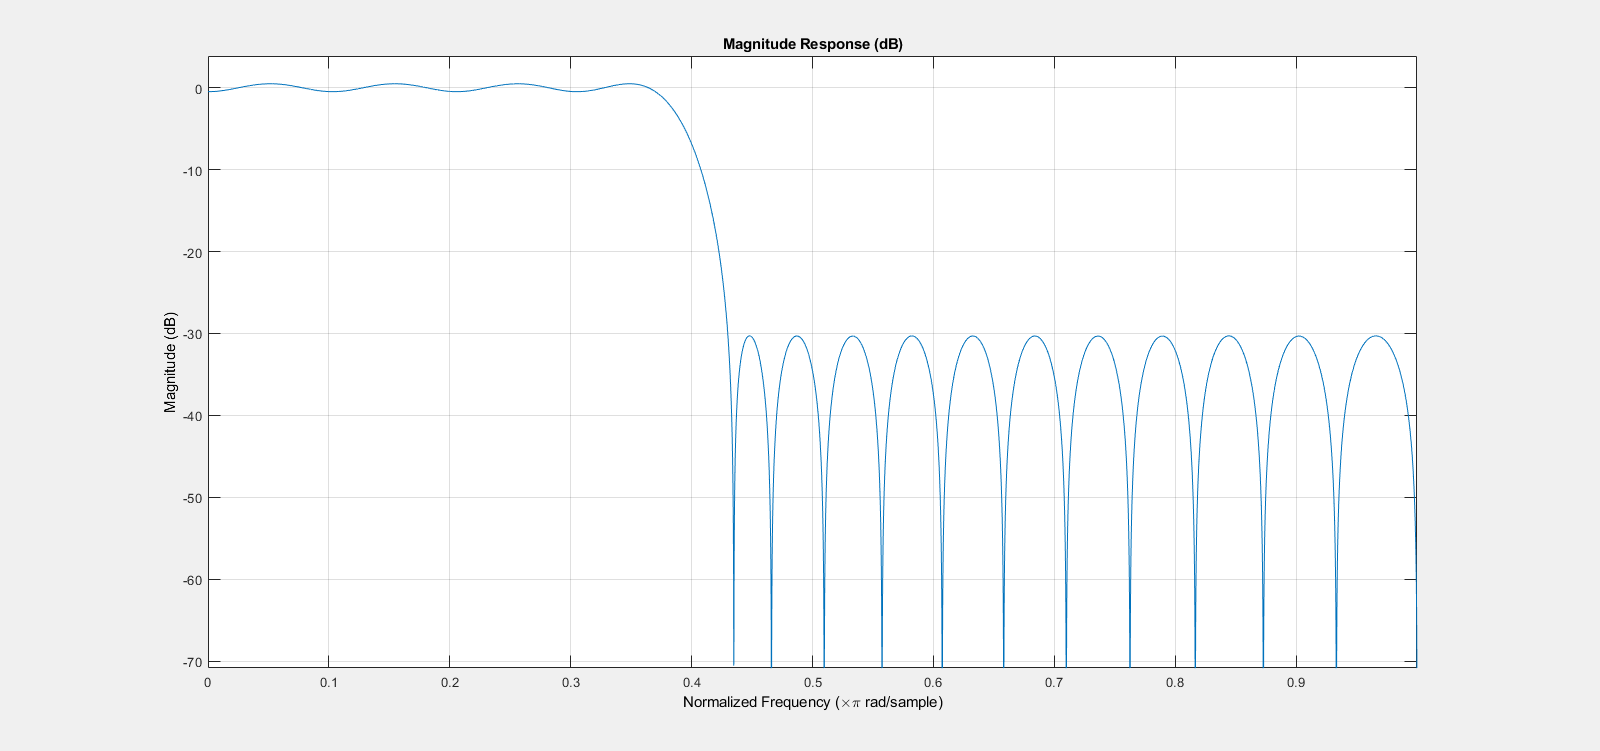

hfvt =   Figure (filtervisualizationtool) with properties:

      Number: 2
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 1600 751]
       Units: 'pixels'

  Use get to show all properties


% Filter Order

% Passband Frequency
Fpass = 0.37;

% Stopband Frequency
Fstop = 0.43;

% PassBand Ripple
Ap = 1;

% Stopband Attentuation (-dB)
Ast = 30;

% Design Filter
df = designfilt('lowpassfir' , ...
    'PassbandFrequency', Fpass, ...
    'StopbandFrequency' , Fstop, ... 
    'PassbandRipple', Ap,...
    'StopbandAttenuation', Ast);
info(df);
hfvt = fvtool(df)

df = designfilt('lowpassfir' , ...
    'PassbandFrequency', Fpass, ...
    'StopbandFrequency' , Fs, ... 
    'PassbandRipple', Ap,...
    'StopbandAttenuation', Ast,...
    "DesignMethod" , 'kaiserwin');

Error using designfilt (line 364)

Click here to launch an assistant to help you design your filter.

Parameter StopbandAttentuation is not recognized.


hfvt = fvtool(df,dw);
legend(hfvt, "Eqiripple", "Window" );

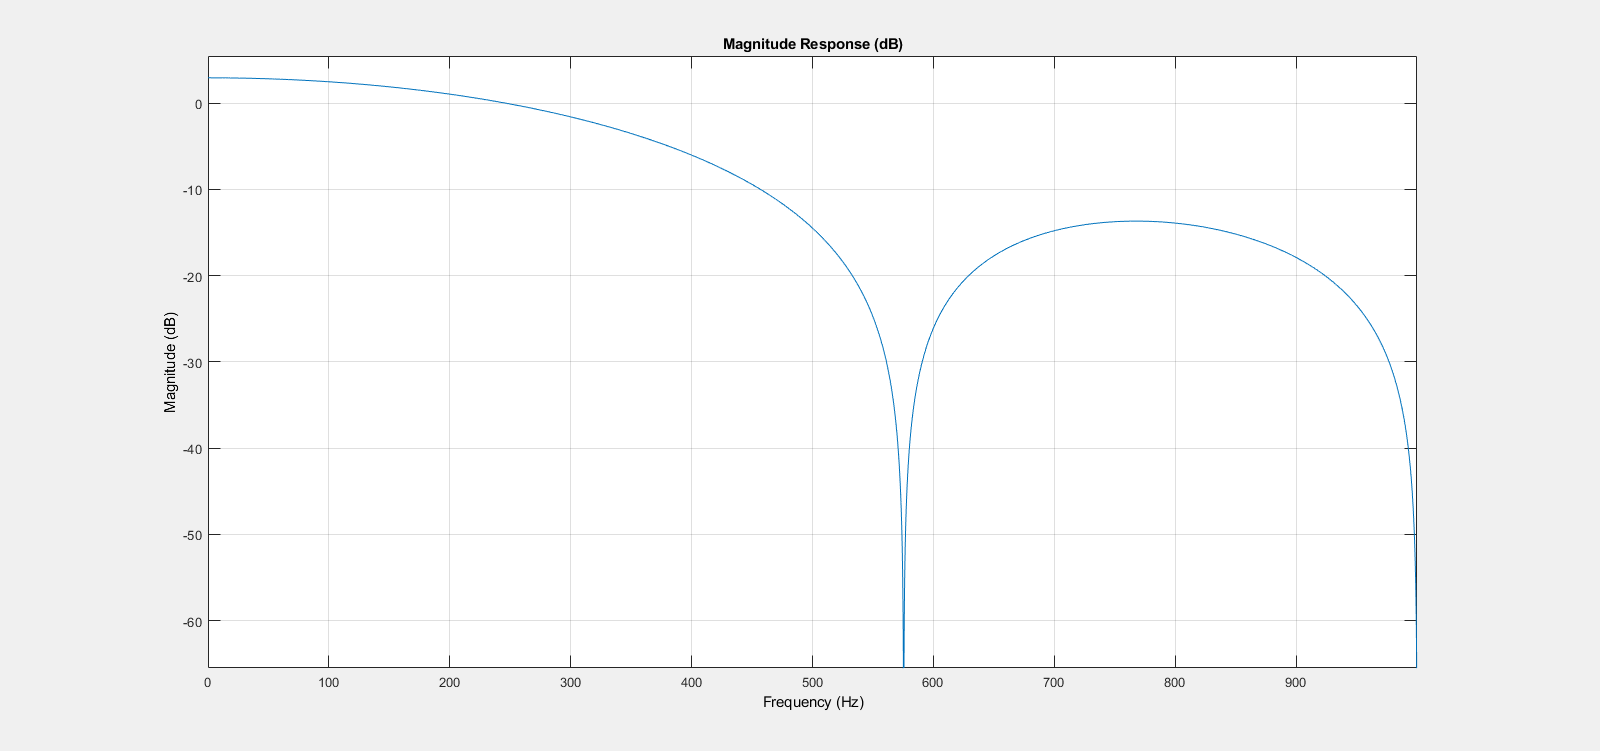

hfvt =   Figure (filtervisualizationtool) with properties:

      Number: 1
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 1600 751]
       Units: 'pixels'

  Use get to show all properties


N = 3;
Fpass = 370; %Hz
Fstop = 430; 
Fsample = 2000;

df = designfilt("lowpassfir",...
    "FilterOrder",N,...
    "PassbandFrequency", Fpass,...
    "StopbandFrequency",Fstop,...
    "SampleRate", Fsample);
hfvt = fvtool(df)
